# Trabajo práctico: Filtrado digital IIR

## 1) Filtro Leaking Integrator (LI) con señales senoidales en MATLAB

### a) Genere una señal senoidal con frecuencia fundamental de 100 Hz.

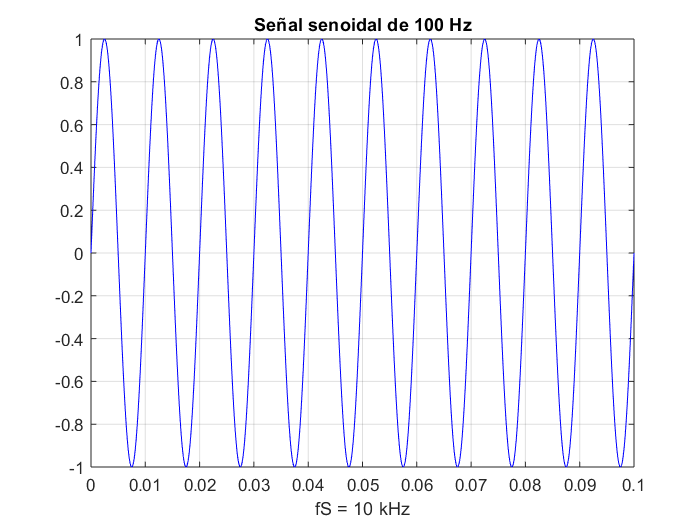

fN = 100; fS = 10e3;
dt = 1/fS;
t = 0:dt:0.1;
signal = sin(2*pi*fN*t);

plot(t, signal, '-b');
title("Señal senoidal de 100 Hz");
xlabel("fS = 10 kHz");
grid on;

### b) Agregue ruido a la señal senoidal tal que la relación señal-ruido entre la señal senoidal y la señal con ruido sea de 15 dB.

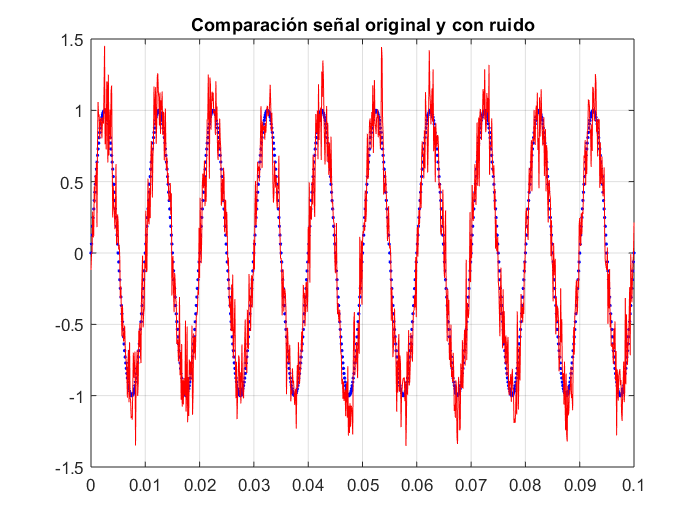

snr = 15;
signal_n = awgn(signal, snr);

plot(t, signal, '.b');
title("Comparación señal original y con ruido");
hold on;
plot(t, signal_n, '-r');
grid on;
hold off;

### c) Diseñe un filtro leaking integrator (LI) con $\lambda$ igual a 0.7.

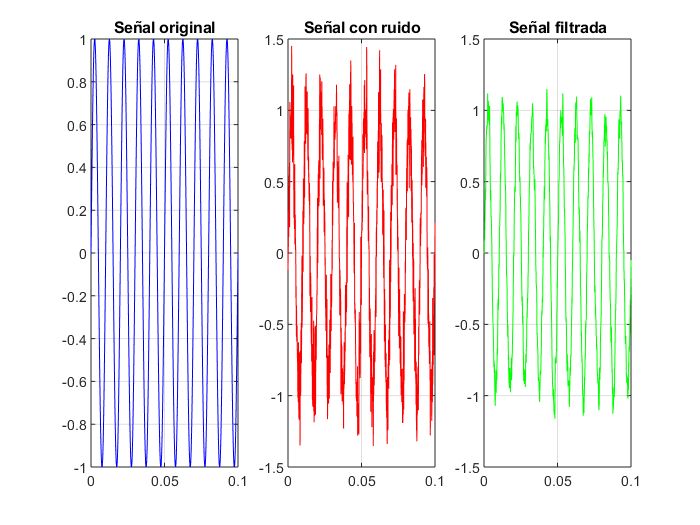

lambda = 0.7;
signal_f = zeros(1, length(signal));
for i=2:length(signal_f)
    signal_f(i) = lambda*signal_f(i-1) + (1 - lambda)*signal_n(i);
end

subplot(1, 3, 1);
plot(t, signal, '-b');
title("Señal original");
grid on;
subplot(1, 3, 2);
plot(t, signal_n, '-r');
title("Señal con ruido");
grid on;
subplot(1, 3, 3);
plot(t, signal_f, '-g');
title("Señal filtrada");
grid on;

### d) Grafique la respuesta en frecuencia y fase del filtro LI. Use la función freqz(). Determine la frecuencia de corte con:

### 
$$fco = -ln(\lambda) / \pi \cdot fs$$


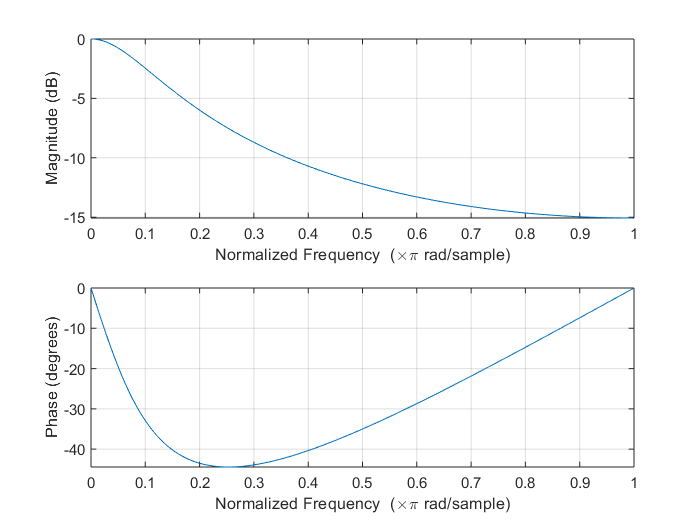

freqz((1-lambda), [1 -lambda]);

fco = -log(lambda)/(pi*fS);
disp("fco = " + fco);

fco = 1.1353e-05


### e) Determine el zero y el polo del filtro con la función zplane(). ¿Es el filtro estable?

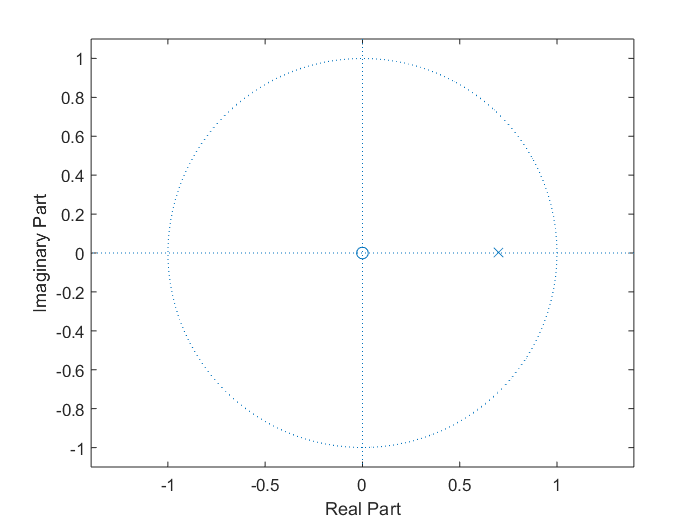

zplane((1-lambda), [1 -lambda]);

El filtro es **estable** (el polo se encuentra dentro de la circunferencia de radio unitario).

### f) Aplique el filtro LI a la señal conruido. Utilice la función filter().

clear signal_f;
signal_f = filter((1-lambda), [1 -lambda], signal_n);

### g) Grafique la respuesta en el tiempo de las señales original y filtrada y compare.

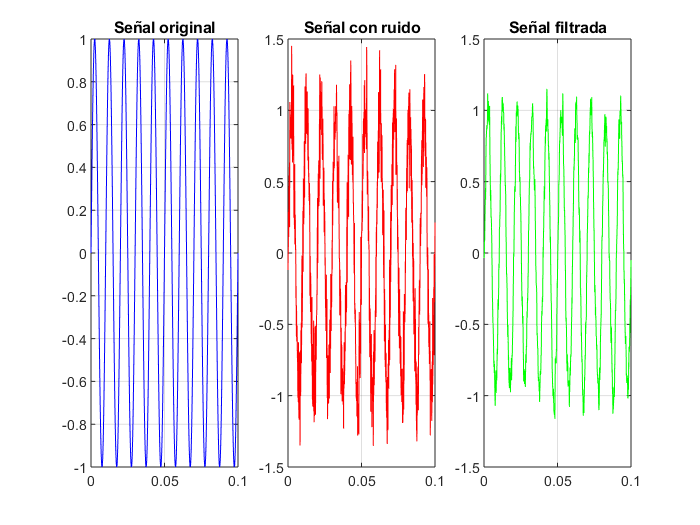

subplot(1, 3, 1);
plot(t, signal, '-b');
title("Señal original");
grid on;
subplot(1, 3, 2);
plot(t, signal_n, '-r');
title("Señal con ruido");
grid on;
subplot(1, 3, 3);
plot(t, signal_f, '-g');
title("Señal filtrada");
grid on;

### h) Grafique la respuesta en frecuencia de las señales original y filtrada y compare.

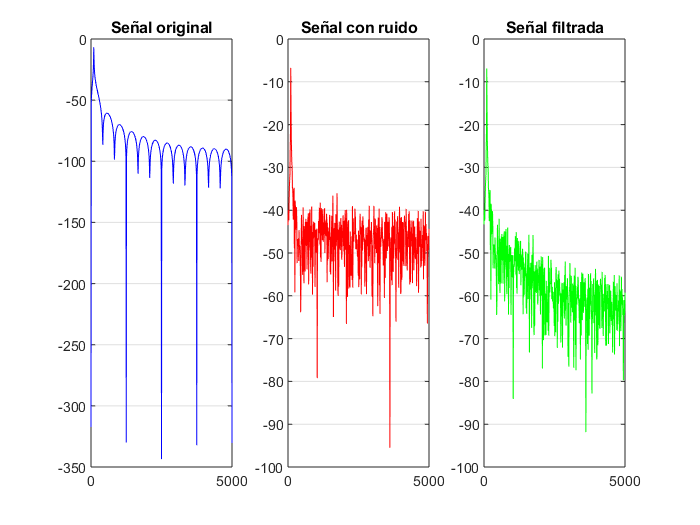

data = [signal; signal_n; signal_f];
[f, dft_mag, dft_phase, ~, ~] = my_dft(data, fS);

subplot(1, 3, 1);
plot(f, mag2db(dft_mag(:, 1)), '-b');
title("Señal original");
grid on;
subplot(1, 3, 2);
plot(f, mag2db(dft_mag(:, 2)), '-r');
title("Señal con ruido");
grid on;
subplot(1, 3, 3);
plot(f, mag2db(dft_mag(:, 3)), '-g');
title("Señal filtrada");
grid on;

### i) Repita los puntos c) a h) para $\lambda$ igual a 0.9 y 0.98. Analice el comportamiento de la fco.

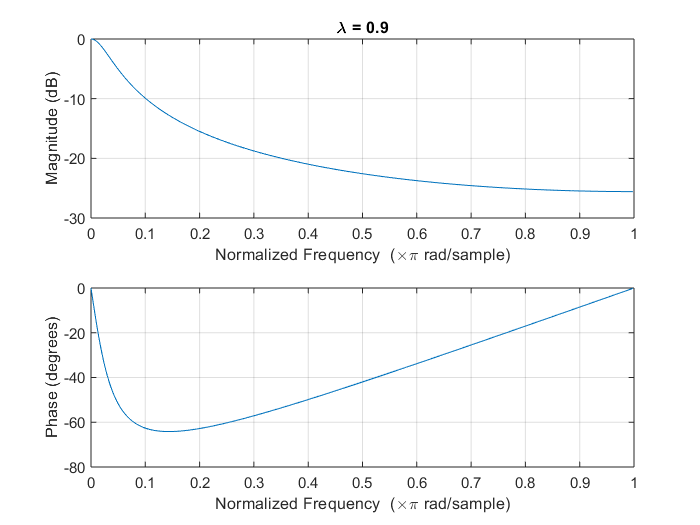

lambda_v = [0.9 0.98];
freqz((1-lambda_v(1)), [1 -lambda_v(1)]);
title("\lambda = 0.9");

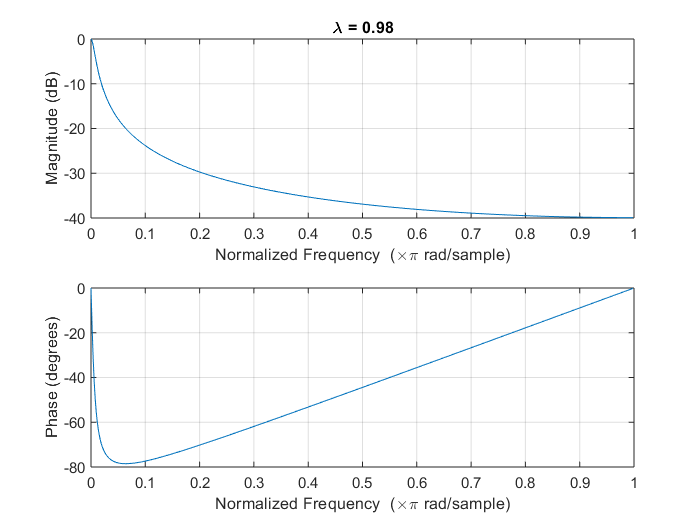

freqz((1-lambda_v(2)), [1 -lambda_v(2)]);
title("\lambda = 0.98");

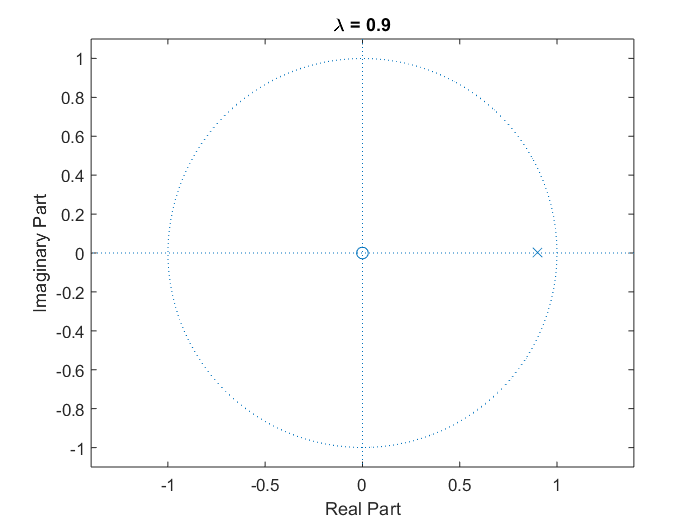

zplane((1-lambda_v(1)), [1 -lambda_v(1)]);
title("\lambda = 0.9");

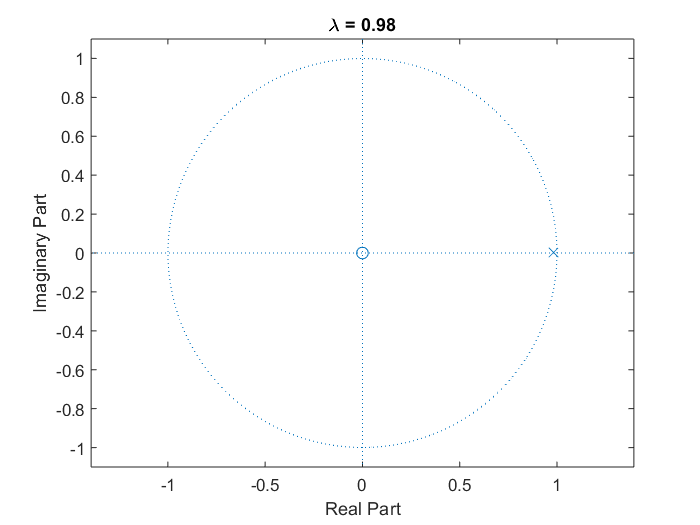

zplane((1-lambda_v(2)), [1 -lambda_v(2)]);
title("\lambda = 0.98");

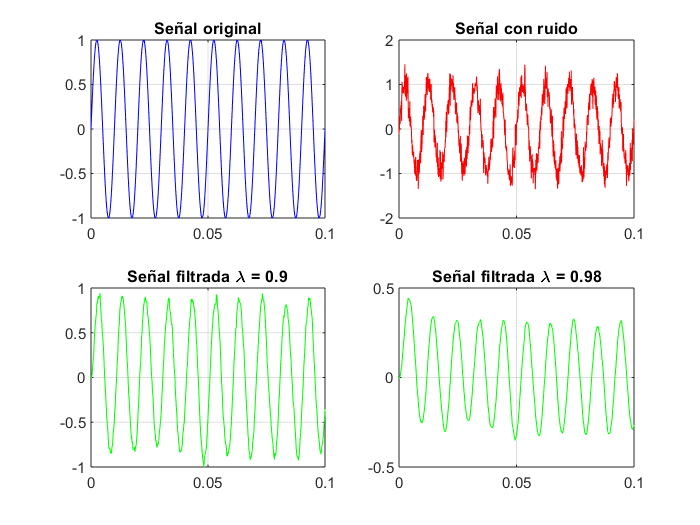

signal_f1 = filter((1-lambda_v(1)), [1 -lambda_v(1)], signal_n);
signal_f2 = filter((1-lambda_v(2)), [1 -lambda_v(2)], signal_n);

subplot(2, 2, 1);
plot(t, signal, '-b');
title("Señal original");
grid on;
subplot(2, 2, 2);
plot(t, signal_n, '-r');
title("Señal con ruido");
grid on;
subplot(2, 2, 3);
plot(t, signal_f1, '-g');
title("Señal filtrada \lambda = 0.9");
grid on;
subplot(2, 2, 4);
plot(t, signal_f2, '-g');
title("Señal filtrada \lambda = 0.98");
grid on;

Análisis del comportamiento de la frecuencia de corte en función del labda del filtro leaking integrator.

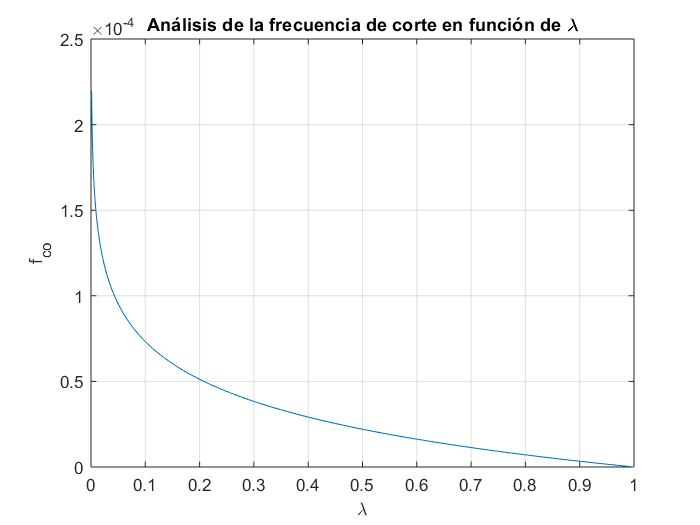

lambda_v = 0:0.001:1;
fco_v = -log(lambda_v)/(pi*fS);

figure;
plot(lambda_v, fco_v);
title("Análisis de la frecuencia de corte en función de \lambda");
xlabel("\lambda");
ylabel("f_{co}");
grid on;